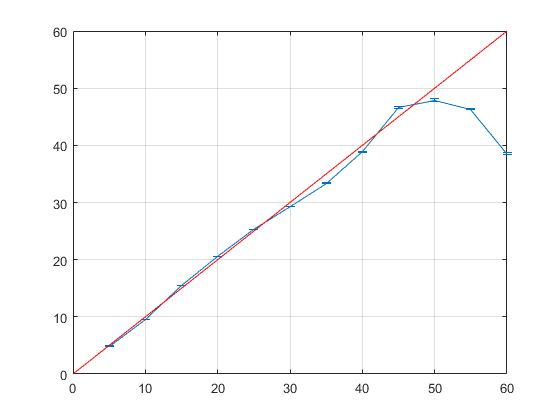

data = csvread('Error Table.csv');
data = data(1:end-7,:);
actual = data(:, 1);
measured = data(:,2:end);

data_mean = mean(measured,2);                         % Mean Across Columns
data_SEM = std(measured,[],2)/sqrt(size(measured,2));  

errorbar(actual, data_mean, data_SEM, 'vertical')
grid 
hold on
plot([0,60], [0, 60], 'r')